# KINARN_to_PF_code

For presentation 1.29.21

clear; clc; 
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/KINARM_to_psychometric')

## Generate data

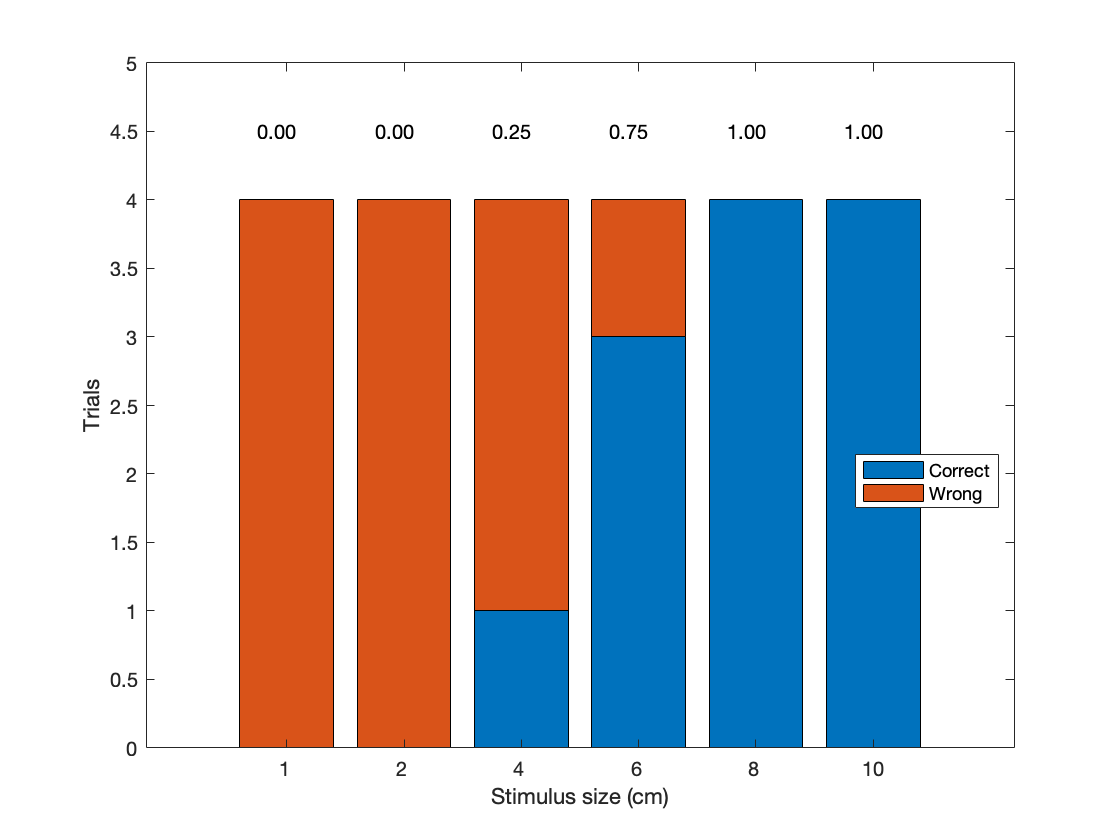

% Hard code data 
Given = struct; 
Given.Size_cm =  [1; 2; 4; 6; 8; 10; 1; 2; 4; 6; 8; 10; 1; 2; 4; 6; 8; 10; 1; 2; 4; 6; 8; 10]; % in centimeters
Given.Direction = {'Up'; 'Down'; 'Left'; 'Right'; 'Up'; 'Down'; 'Left'; 'Right'; 'Up'; 'Down'; 'Left'; 'Right'; 'Up'; 'Down'; 'Left'; 'Right'; 'Up'; 'Down'; 'Left'; 'Right'; 'Up'; 'Down'; 'Left'; 'Right'};
Given.Choice =    {'Down'; 'Up'; 'Left'; 'Right'; 'Up'; 'Down'; 'Down'; 'Up'; 'Down'; 'Down'; 'Left'; 'Right'; 'Down'; 'Up'; 'Right'; 'Right'; 'Up'; 'Down'; 'Down'; 'Up'; 'Left'; 'Right'; 'Left'; 'Right'};
Given = struct2table(Given);
% Randomize
rnd = datasample(1:24, 24, 'replace', false);
for i = 1:size(Given,1)
    Given_rnd(i,:) = Given(rnd(i),:);
end
% Determine if correct 
for i = 1:size(Given_rnd,1)
    if strcmp(Given_rnd.Direction(i), Given_rnd.Choice(i))
        Given_rnd.Correct(i) = 1;
    else 
        Given_rnd.Correct(i) = 0;
    end
end
% Group data by stimulus size 
Bplt = zeros(6,2); % rows = stimulus size (increasing); columns = # of correct trials, # of total trials 
for i = 1:size(Given_rnd,1)
    switch Given_rnd.Size_cm(i)
        case 1 
            Bplt(1,1) = Bplt(1,1) + Given_rnd.Correct(i);
            Bplt(1,2) = Bplt(1,2)+1;
        case 2 
            Bplt(2,1) = Bplt(2,1) + Given_rnd.Correct(i);
            Bplt(2,2) = Bplt(2,2)+1;
        case 4 
            Bplt(3,1) = Bplt(3,1) + Given_rnd.Correct(i);
            Bplt(3,2) = Bplt(3,2)+1;
        case 6 
            Bplt(4,1) = Bplt(4,1) + Given_rnd.Correct(i);
            Bplt(4,2) = Bplt(4,2)+1;
        case 8 
            Bplt(5,1) = Bplt(5,1) + Given_rnd.Correct(i);
            Bplt(5,2) = Bplt(5,2)+1;
        case 10
            Bplt(6,1) = Bplt(6,1) + Given_rnd.Correct(i);
            Bplt(6,2) = Bplt(6,2)+1;
    end
end
Bplt(:,3) = Bplt(:,1) ./ Bplt(:,2);
% Calculate p(correct) for each stimulus size 
figure;
bar([0 4; 0 4; 1 3; 3 1; 4 0; 4 0], 'stacked')
hold on 
legend('Correct', 'Wrong', 'location', 'best')
set(gca, 'xticklabels', [1 2 4 6 8 10]);
xlabel('Stimulus size (cm)')
ylabel('Trials')
ylim([0 5])
for i = 1:size(Bplt,1)
    text(i-0.25, 4.5, sprintf('%.2f', Bplt(i,3)))
end

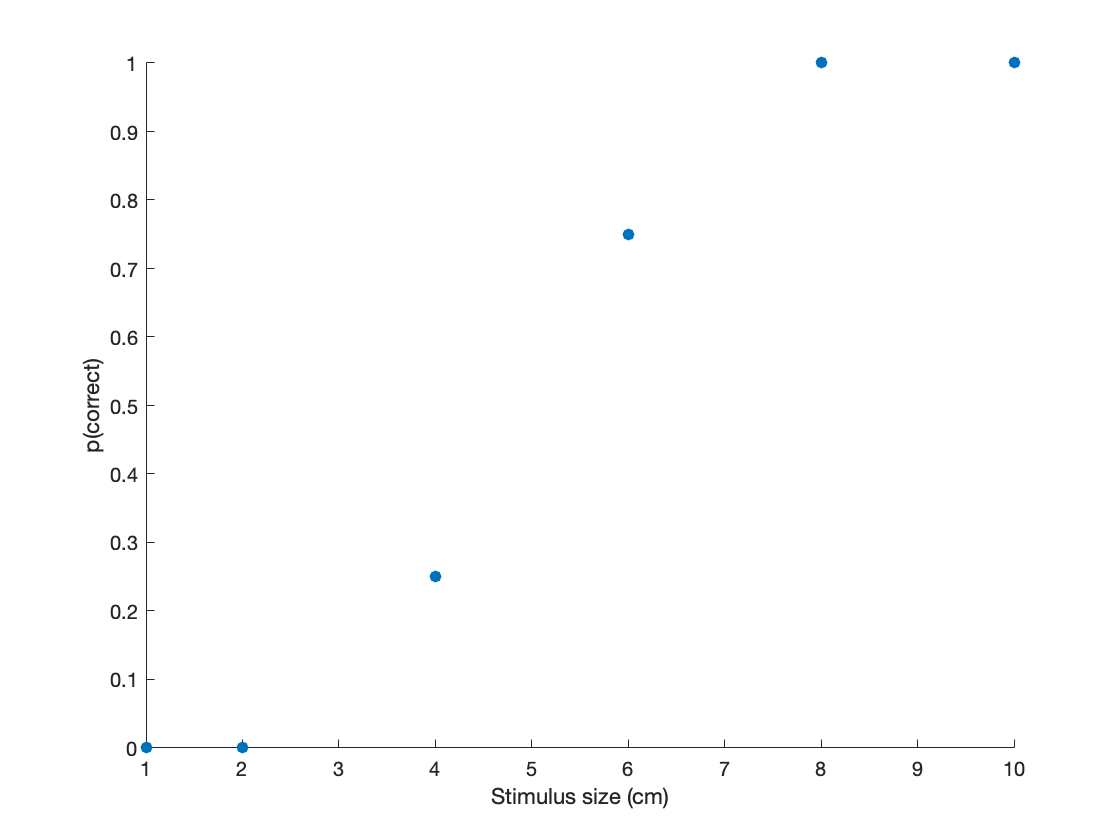

figure;
scatter([1,2,4,6,8,10], [0 0 .25 0.75 1 1], [], 'filled')
xlabel('Stimulus size (cm)'); ylabel('p(correct)')

% just_save('pscyh_ex_nofit', 'n')

## New equation and fits 

Four parameter model: 


$$\psi \left(x;\alpha ,\beta ,\gamma ,\lambda \right)=\gamma +\left(1-\gamma -\lambda \right)F\left(x;\alpha ,\beta \right)$$


Parameters


$$\begin{array}{l}
\psi :\textrm{proportion}\;\textrm{of}\;\textrm{correct}\;\textrm{responses}\;\\
x:\textrm{data}\;\\
\alpha :\textrm{midpoint}\;\textrm{OR}\;\textrm{threshold}\\
\beta :\textrm{heat}\;\textrm{OR}\;\textrm{slope}\\
\gamma :\textrm{guess}\;\textrm{rate}\;\textrm{OR}\;\textrm{lower}\;\textrm{asymptote}\;\textrm{of}\;\psi \;\\
\lambda :\textrm{lapse}\;\textrm{rate}\;\textrm{OR}\;\textrm{upper}\;\textrm{asymptote}\;\textrm{of}\;\psi \;\\
F:\textrm{sigmoid}\;\textrm{function}\;\left(\textrm{Weibull},\textrm{logistic},\textrm{gumbel},\textrm{cumulative}\;\textrm{normal},\textrm{hyperbolic}\;\textrm{secand},\textrm{quick}\right)
\end{array}$$


% values 
xdata = unique(Given.Size_cm); 
trials = Bplt(:,2);
correct = Bplt(:,1); 
p_correct = correct ./ trials; 

% Create function to use (with logistic)
fun = @(x,xdata) x(4) + (1 - x(4) - x(3)) * (1 ./ (1 + exp(-x(2)*(xdata - x(1))))); % alpha, beta, lambda, gamma

% Initial guess for [alpha, beta, lambda, gamma] parameter 
x0 = [5 3 0 0];
                
% Minimize negative log likelihood 
coeffs = fmincon(@(x) nloglik_1(x(1), x(2), x(3), x(4), xdata, trials, correct), x0, [], [], [], [], [min(xdata) 0 0 0], [max(xdata) 10 1 1]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


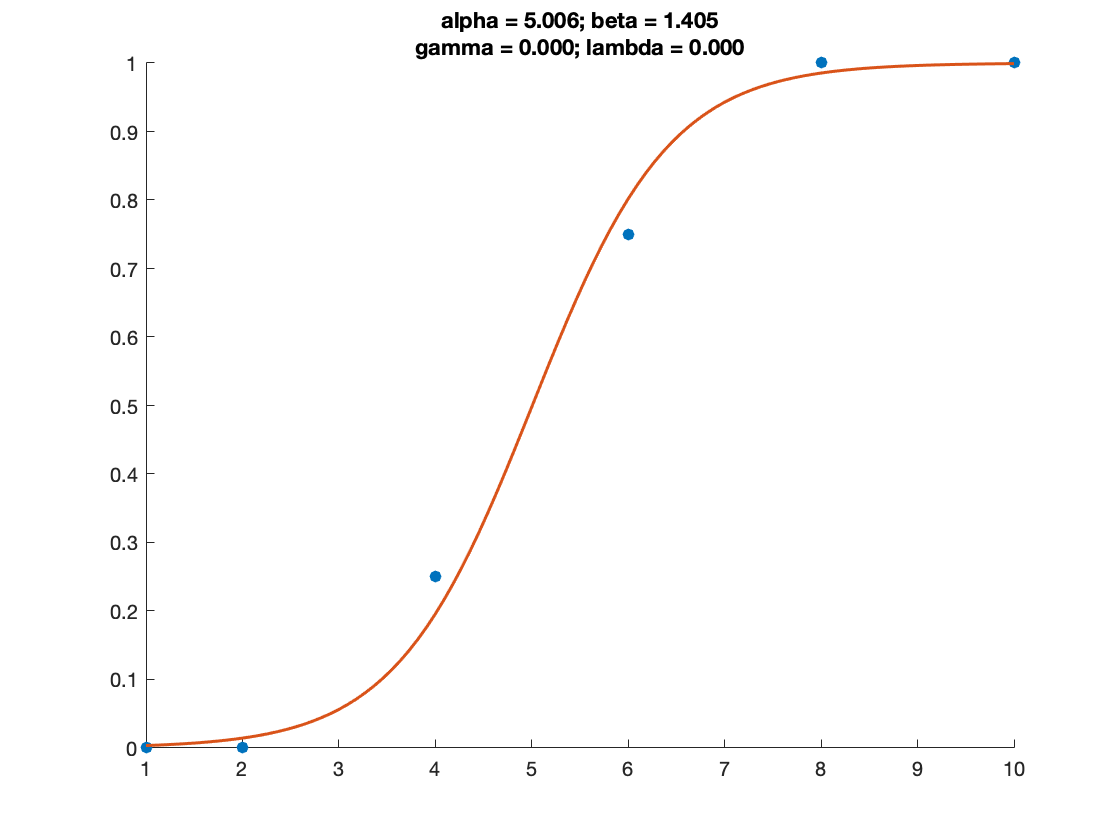

% plot 
figure;
scatter(xdata, p_correct, [], 'filled');
hold on 
xL = linspace(xdata(1), xdata(length(xdata))); 
yL = fun(coeffs, linspace(xdata(1), xdata(length(xdata))));
plot(xL, yL, 'linewidth', 1.5)
title(sprintf('alpha = %.3f; beta = %.3f\ngamma = %.3f; lambda = %.3f', coeffs(1), coeffs(2), coeffs(3), coeffs(4)))

## Changing parameters

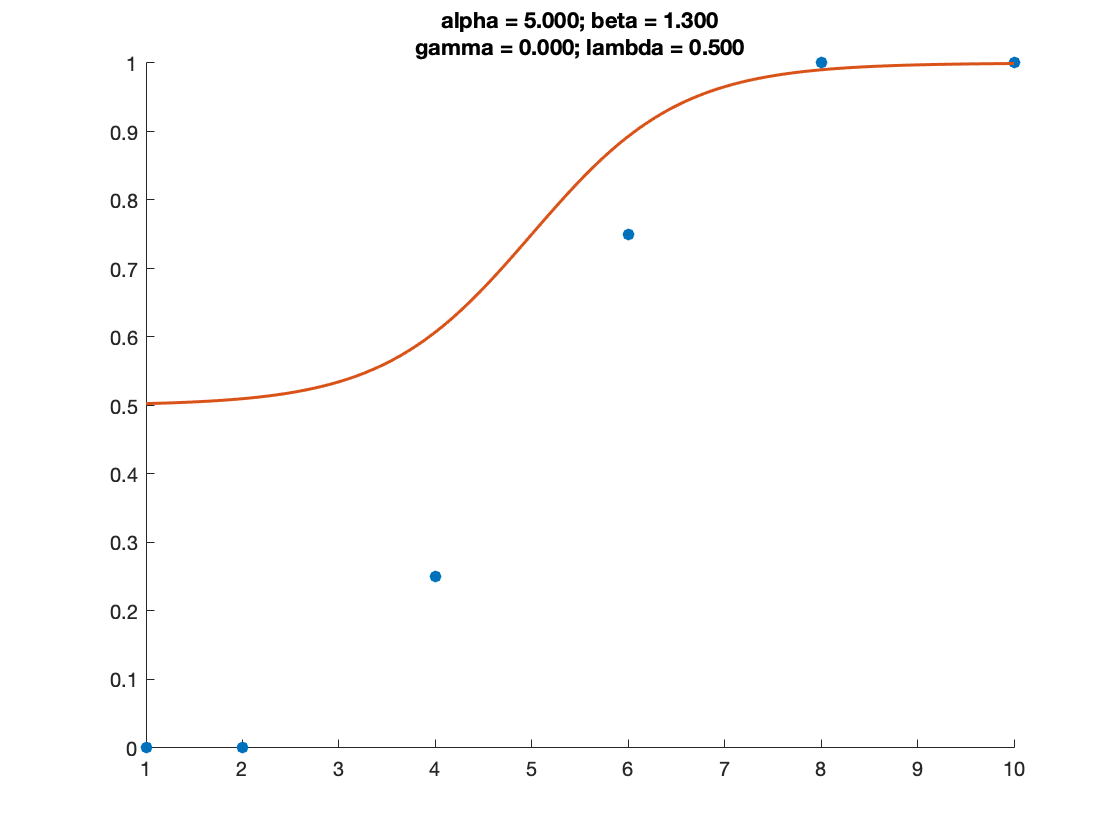

alpha = 5;
beta = 1.3; 
lambda = 0;
gamma = 0.5; 

% plot 
figure;
scatter(xdata, p_correct, [], 'filled');
hold on 
yL = fun([alpha, beta, lambda, gamma], linspace(xdata(1), xdata(length(xdata))));
plot(xL, yL, 'linewidth', 1.5)
title(sprintf('alpha = %.3f; beta = %.3f\ngamma = %.3f; lambda = %.3f', alpha, beta, lambda, gamma))

What predictions can we make about parameter values for each of the 3 groups of subjects? 

## Non-parametric bootstrap

Simulate many experiments using the observers data 

nboots = 500; % number of bootstraps / simulated experiments 
b_coeffs = nan(nboots, 4); 
for i = 1:nboots
    % resample with replacement 
    for ii = 1:length(xdata)
        true_data = Given_rnd.Correct(Given_rnd.Size_cm == xdata(ii)); 
        sim_corr = datasample(true_data, length(true_data), 'replace', true);
        sim_correct(ii,1) = sum(sim_corr); 
    end
    % fit a psychometric function 
    b_coeffs(i,:) = fmincon(@(x) nloglik_1(x(1), x(2), x(3), x(4), xdata, trials, sim_correct), x0, [], [], [], [], [min(xdata) 0 0 0], [max(xdata) 10 1 1]);
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

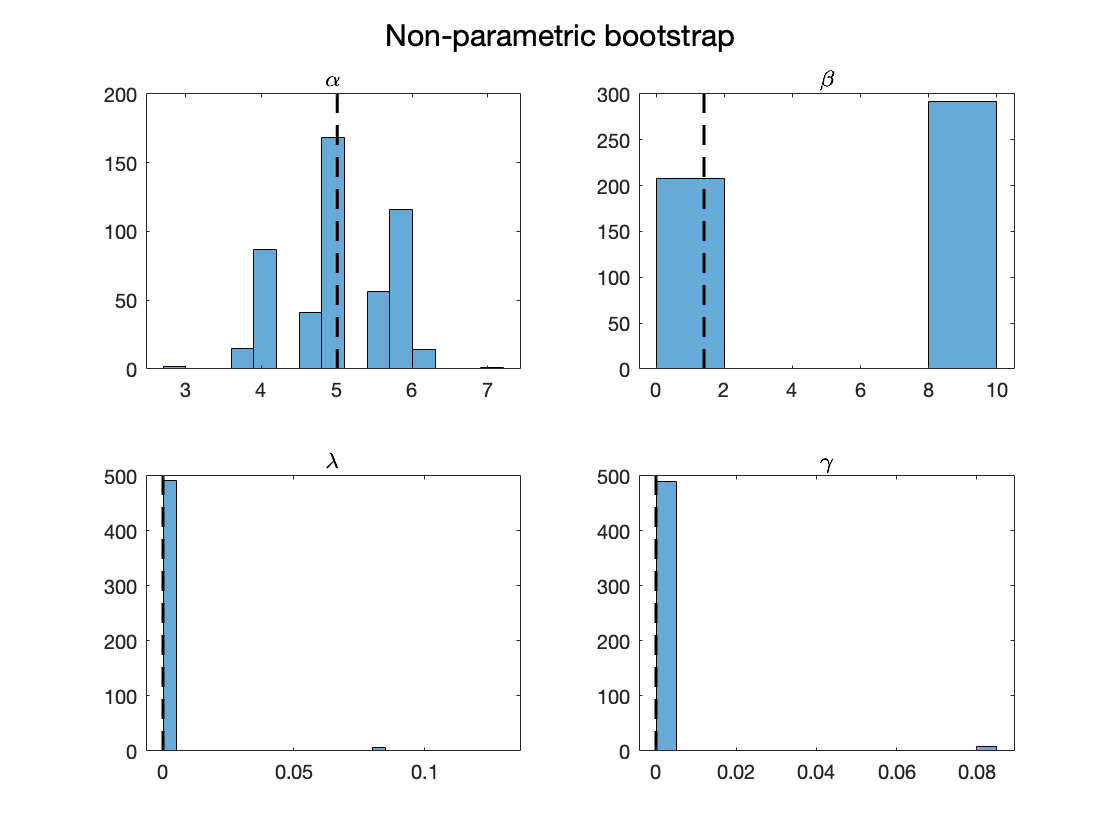

% Plot distribution for all parameters 
figure; 
for i = 1:size(b_coeffs,2)
    subplot(2,2,i);
    histogram(b_coeffs(:,i))
    hold on 
    if i == 1
        vline(coeffs(1), 'k', '--', 1.5); 
        title('\alpha')
    elseif i == 2
        vline(coeffs(2), 'k', '--', 1.5); 
        title('\beta')
    elseif i == 3
        vline(coeffs(3), 'k', '--', 1.5); 
        title('\lambda')
    else 
        vline(coeffs(4), 'k', '--', 1.5); 
        title('\gamma')
        sgtitle('Non-parametric bootstrap')
    end
end

## Parametric Bootstrap

Simulate many experiments using the observers parameters

function nll = nloglik_1(alpha, beta, lambda, gamma, signal_intensity, trials, correct)
% INPUTS:
% alpha: threshold / PSE (point of subjective equality)
% beta: slope / rate of change / heat
% lambda: lapse rate (probability of an incorrect response, which is
% independent of stimulus intensity) 
% gamma: guess rate (probability of a correct response when the stimulus is
% not detected by the underlying sensory mechanism)

% OUTPUT:
% nll: negative log likelihood 


Deriving negative log likelihood from likelihood of a binomial distribution. 

Write out likelihood of a binomial distribution, where *n *denotes total number of trials sampled at each stimuli, *x *denotes number of correct trials, and *p* denotes probabilities from psychometric function. 

$L\left(p;x\right)=\frac{n!}{x!\left(n-x\right)!}p^x {\left(1-p\right)}^{n-x}$                                (1)

Take the negative log of equation 1. 

$=-\log \left\lbrack \frac{n!}{x!\left(n-x\right)!}p^x {\left(1-p\right)}^{n-x} \right\rbrack$                                 (2)

Distribute the log. 

$=-\log \left(\frac{n!}{x!\left(n-x\right)!}\right)+\;\log \left(p^x \right)\;+\;\log \left({\left(1-p\right)}^{n-x} \right)$        (3)

Note: Log rule: log(a*b) = log(a) + log(b)

Remove constant, distribute exponents and negative sign. 

$=-\textrm{xlog}\left(p\right)-\left(n-x\right)\log \left(1-p\right)$                                     (4)

Note: Log exponent rule: log(a^b) = b*log(a)

% Create psychometric function 
I = gamma + (1 - gamma - lambda) * (1 ./ (1 + exp(-beta*(signal_intensity - alpha)))); 

% find nll 
nll = -sum(correct .* log(I) + (trials - correct) .* log(1 - I)); 

end
